# Fourier Transforms

## Stationary Signal

Fs = 500;
T  = 1;
t  = 0:1/Fs:T;
N  = length(t);

x = sin(2*pi*15*t+pi/4) + sin(2*pi*20*t);

plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')
grid on

### Compute the Fourier Transform

X = fft(x);
f = (0:N-1)*(Fs/N);

### Magnitude before and after shifting

stem(f,abs(X))
xlim([0 30])
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')
grid on
f_shift = (-N/2:N/2-1)*(Fs/N);
X_shift = fftshift(X);
stem(f_shift,abs(X_shift))
xlim([-30 30])
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude (Shifted)')
grid on

### Phase

tol = 1e-6;
X_filtered = X_shift;
X_filtered(abs(X_shift) < tol) = 0;

stem(f_shift, angle(X_filtered)/pi)
xlim([-30 30])
xlabel("Frequency (Hz)")
ylabel("Phase / \pi")
grid on

### **Inverse Fourier Transform**

x_rec = ifft(X);

figure('Name','Reconstruction comparison','Color','w');
subplot(2,1,1);
plot(t, x, 'b', 'DisplayName','Original'); hold on;
plot(t, x_rec, 'r--', 'DisplayName','Reconstructed');
xlabel('Time [s]'); ylabel('Amplitude');
title('x(t) and reconstructed x_{rec}(t)');
legend; grid on;

subplot(2,1,2);
plot(t, x - x_rec, 'k');
xlabel('Time [s]'); ylabel('Error');
title(sprintf('Reconstruction Error (max = %.2e)', max(abs(x - x_rec))));
grid on;
figure;

## Non-Stationary signal

Fs = 1000;
T  = 1;
t  = 0:1/Fs:T;
N  = length(t);

frq1 = 32;
amp1 = 1;
frq2 = 64;
amp2 = 2;

x = amp1*sin(2*pi*frq1*t).*(t>=0.1 & t<0.3)+... 
    amp2*sin(2*pi*frq2*t).*(t>0.6 & t<0.9);

plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')
grid on

### Compute the Fourier Transform

X = fft(x);
f = (0:N-1)*(Fs/N);

### Magnitude before and after shifting

stem(f,abs(X))
xlim([0 100])
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')
grid on
f_shift = (-N/2:N/2-1)*(Fs/N);
X_shift = fftshift(X);
stem(f_shift,abs(X_shift))
xlim([-100 100])
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude (Shifted)')
grid on

### Phase

tol = 1e-6;
X_filtered = X_shift;
X_filtered(abs(X_shift) < tol) = 0;

stem(f_shift, angle(X_filtered)/pi)
xlim([-100 100])
xlabel("Frequency (Hz)")
ylabel("Phase / \pi")
grid on

### **Inverse Fourier Transform**

x_rec = ifft(X);

figure('Name','Reconstruction comparison','Color','w');
subplot(2,1,1);
plot(t, x, 'b', 'DisplayName','Original'); hold on;
plot(t, x_rec, 'r--', 'DisplayName','Reconstructed');
xlabel('Time [s]'); ylabel('Amplitude');
title('x(t) and reconstructed x_{rec}(t)');
legend; grid on;

subplot(2,1,2);
plot(t, x - x_rec, 'k');
xlabel('Time [s]'); ylabel('Error');
title(sprintf('Reconstruction Error (max = %.2e)', max(abs(x - x_rec))));
grid on;
figure;

### Short Term Fourier Transform

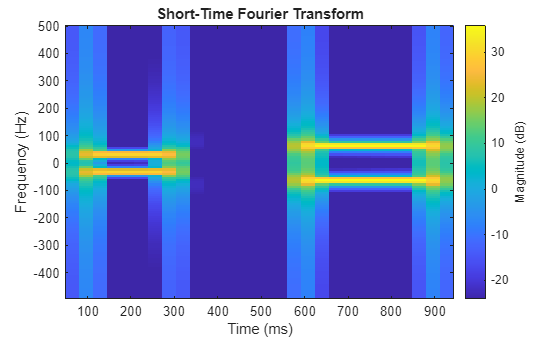

X = stft(x, Fs);
stft(x, Fs)

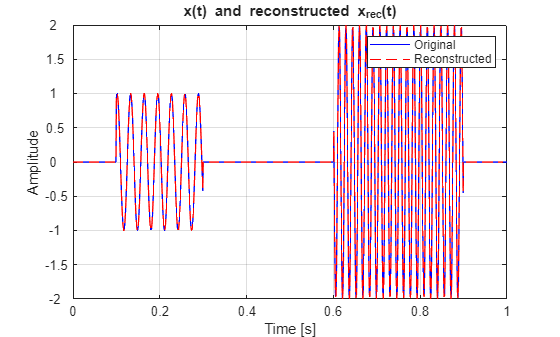

[x_rec, t_rec] = istft(X, Fs);

figure('Name','Reconstruction comparison','Color','w');
plot(t, x, 'b', 'DisplayName','Original'); hold on;
plot(t_rec, x_rec, 'r--', 'DisplayName','Reconstructed');
xlabel('Time [s]'); ylabel('Amplitude');
title('x(t) and reconstructed x_{rec}(t)');
legend; grid on;

### Continuous Wavelet Transform

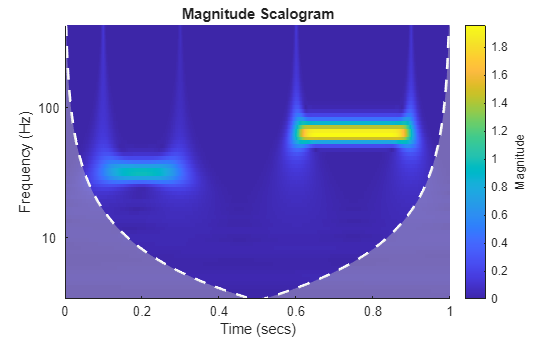

X = cwt(x, Fs);
cwt(x, Fs)

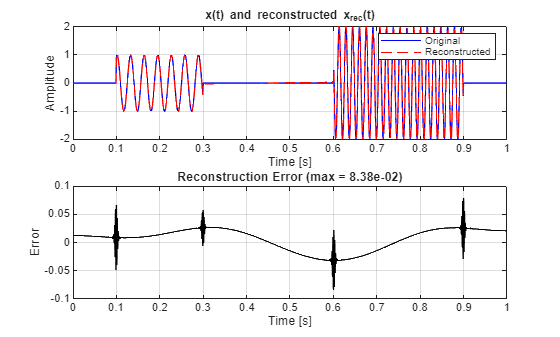

x_rec = icwt(X);

figure('Name','Reconstruction comparison','Color','w');
subplot(2,1,1);
plot(t, x, 'b', 'DisplayName','Original'); hold on;
plot(t, x_rec, 'r--', 'DisplayName','Reconstructed');
xlabel('Time [s]'); ylabel('Amplitude');
title('x(t) and reconstructed x_{rec}(t)');
legend; grid on;

subplot(2,1,2);
plot(t, x - x_rec, 'k');
xlabel('Time [s]'); ylabel('Error');
title(sprintf('Reconstruction Error (max = %.2e)', max(abs(x - x_rec))));
grid on;

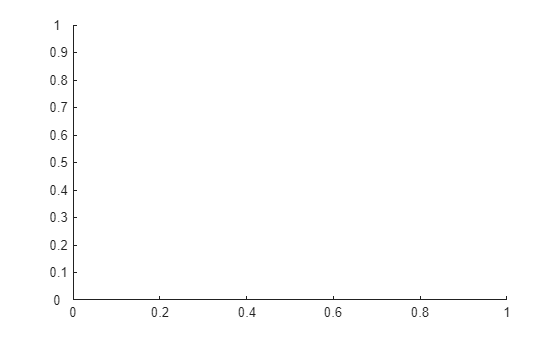

figure;